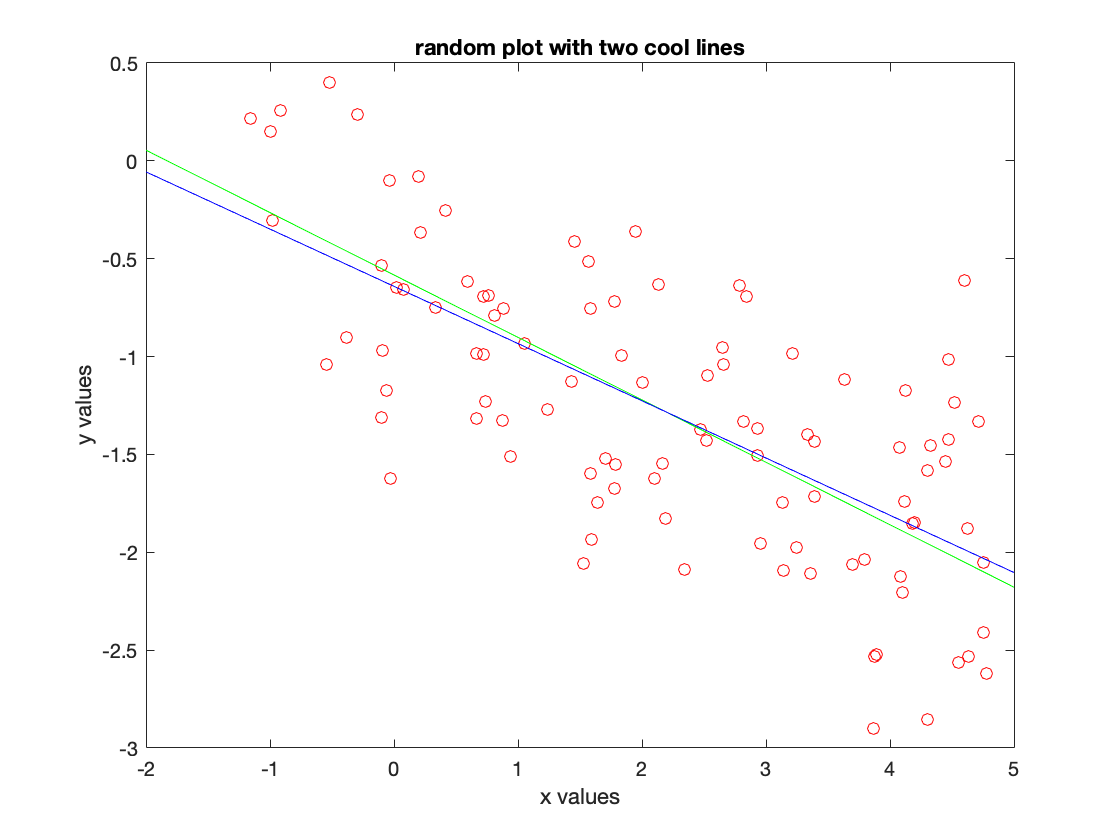

a;
b;
rho = corrcoef(a, b);
rho = rho(1,2);
sa = std(a); sb = std(b);
ma = mean(a); mb = mean(b);
coeff = [rho sa/sb-sb/sa -rho];
r = roots(coeff);
% rho is negative -0.6959, therefore we choose the negative coefficient aka
% the first element
c2 = r(1);
c1 = mb - ma * c2;

figure(1);
hold on;
scatter(a, b, 'red');
plot(x, x * c2 + c1, 'green');

A = [ones(length(a),1) a];
linreg = A\b;
plot(x, linreg(1) + linreg(2) * x, 'blue');

hold off;

xlabel("x values");
ylabel("y values");
title("random plot with two cool lines");

disp("green line is orthogonal and blue line is regular linreg")

green line is orthogonal and blue line is regular linreg
